% import excel file with zscore data
baseFileName = 'zscores_data.xlsx';
folder = '/users/yikun/Downloads';
fullFileName = fullfile(folder, baseFileName)

fullFileName = '/users/yikun/Downloads/zscores_data.xlsx'

zscore_data = readtable(fullFileName);
zscore_data = zscore_data(:,2:end);
% convert table values to array
zscore_array = table2array(zscore_data(:,2:end));


% plot
yvalues = zscore_data{:,1};
xvalues = zscore_data.Properties.VariableNames(2:end);
h = heatmap(xvalues,yvalues,zscore_array)

h =   HeatmapChart with properties:

        XData: {8×1 cell}
        YData: {200×1 cell}
    ColorData: [200×8 double]

  Show all properties


h.Title = 'z-scores';
h.XLabel = 'Structures';
h.YLabel = 'Subject ID';

% Convert each number in the array into a string
Customyvalues = string(yvalues);
% Replace all but the fifth elements by spaces
Customyvalues(mod(yvalues,25) ~= 0) = " ";
h.YDisplayLabels = Customyvalues

h =   HeatmapChart (z-scores) with properties:

        XData: {8×1 cell}
        YData: {200×1 cell}
    ColorData: [200×8 double]

  Show all properties


grid off
N = 1000

N = 1000

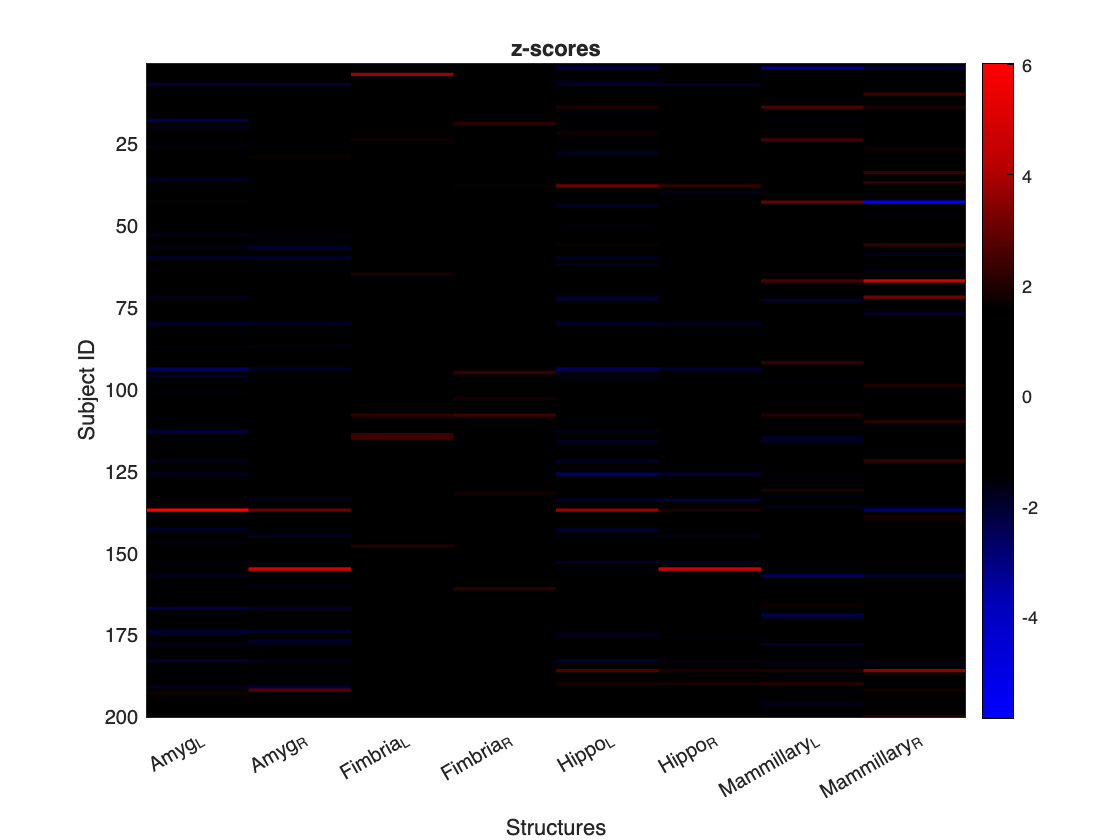

h =   HeatmapChart (z-scores) with properties:

        XData: {8×1 cell}
        YData: {200×1 cell}
    ColorData: [200×8 double]

  Show all properties



h.Colormap = CustomColormap

zscore_data = readtable(fullFileName);
zscore_data = zscore_data(1:15,2:end);
% convert table values to array
zscore_array = table2array(zscore_data(1:15,2:end));


% plot
yvalues = zscore_data{:,1};
y_values = yvalues(1:15)

y_values =      1
     2
     3
     4
     5
     6
     7
     8
     9
    10


x_values = zscore_data.Properties.VariableNames(2:end);
h = heatmap(x_values,y_values,zscore_array)

h =   HeatmapChart with properties:

        XData: {8×1 cell}
        YData: {15×1 cell}
    ColorData: [15×8 double]

  Show all properties


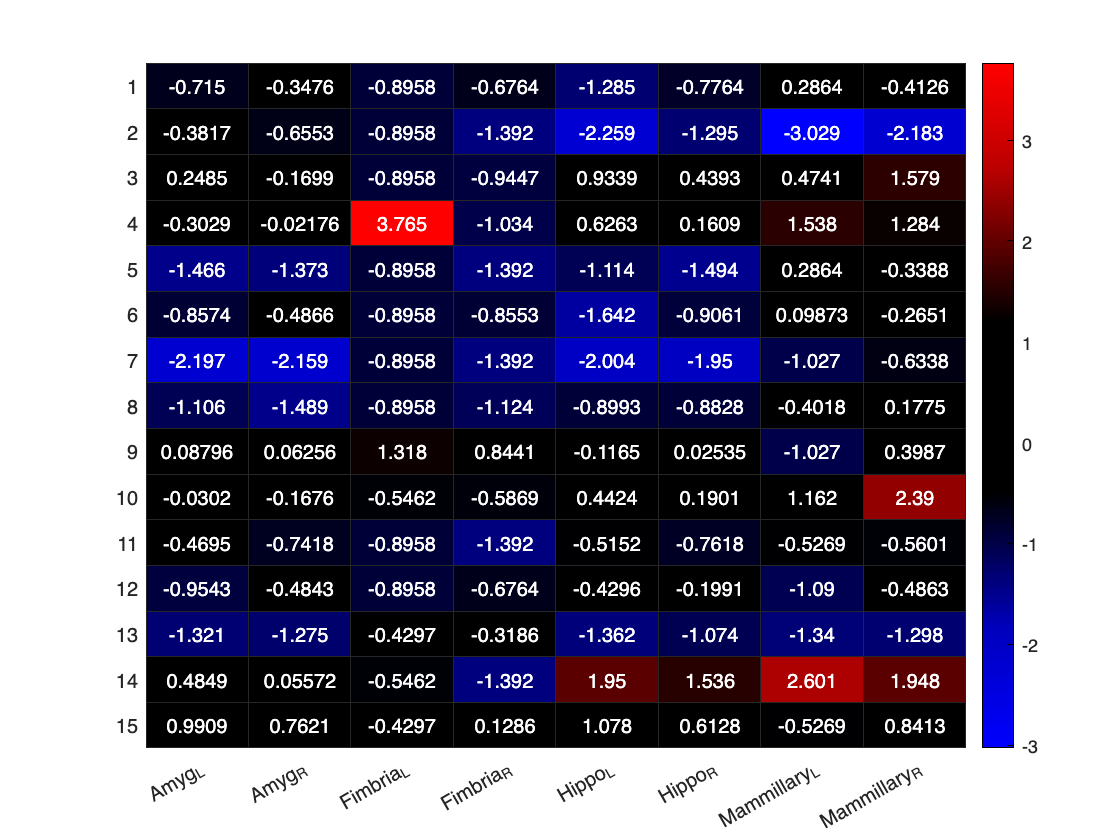

h =   HeatmapChart with properties:

        XData: {8×1 cell}
        YData: {15×1 cell}
    ColorData: [15×8 double]

  Show all properties


h.Colormap = CustomColormap

MNI_baseFileName = 'MNI_zscores_data.xlsx';
folder = '/users/yikun/Downloads';
fullFileName = fullfile(folder, MNI_baseFileName)

fullFileName = '/users/yikun/Downloads/MNI_zscores_data.xlsx'

MNI_zscore_data = readtable(fullFileName);
% convert table values to array
MNI_zscore_array = table2array(MNI_zscore_data(:,2:end));


% plot
MNI_yvalues = MNI_zscore_data{:,1};
MNI_xvalues = MNI_zscore_data.Properties.VariableNames(2:end);
h = heatmap(MNI_xvalues,MNI_yvalues,MNI_zscore_array)

h =   HeatmapChart with properties:

        XData: {8×1 cell}
        YData: {'0'}
    ColorData: [1.1696 0.5753 4.5809 1.2913 2.3793 2.1172 5.0412 4.8240]

  Show all properties


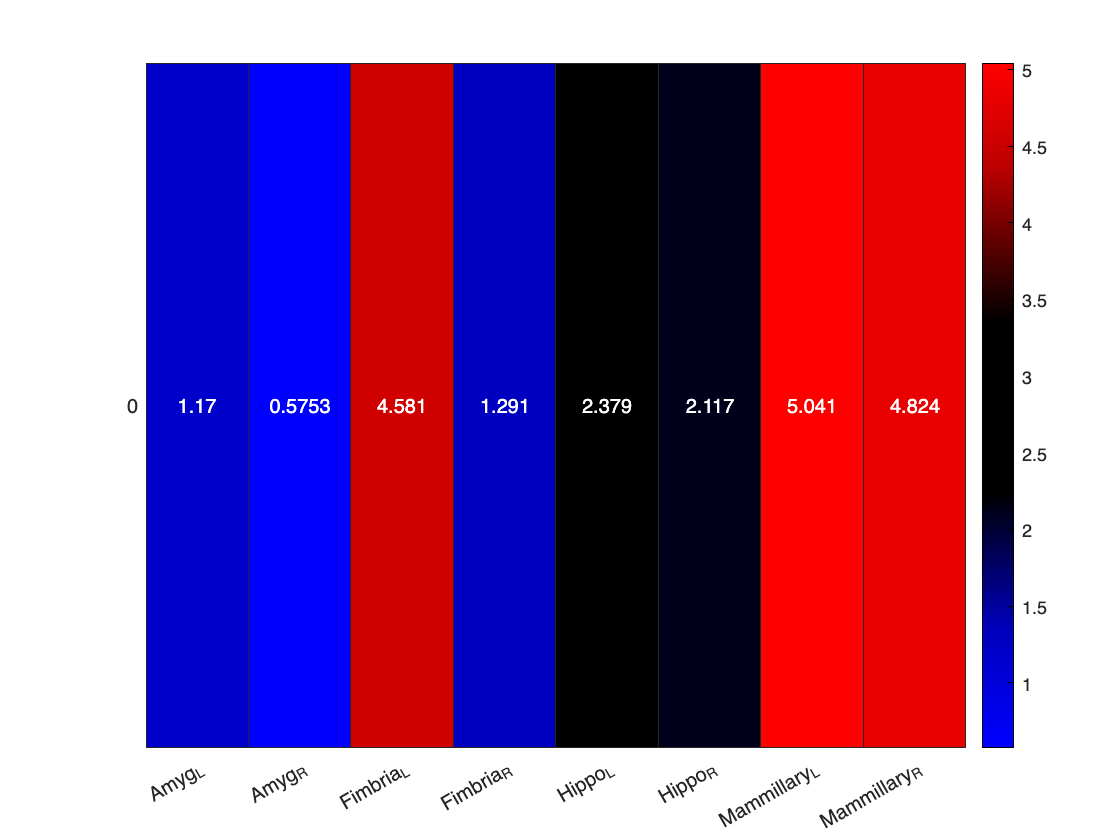

h =   HeatmapChart with properties:

        XData: {8×1 cell}
        YData: {'0'}
    ColorData: [1.1696 0.5753 4.5809 1.2913 2.3793 2.1172 5.0412 4.8240]

  Show all properties


colormapeditor
h.Colormap = CustomColormap